### SET_PARAM_PBESS

created by Prof FGL

This MATLAB life script must run before ruing the Simulink model

This script is working with the siluni model called:  PBESS.mdl

clc
clear

I. Defining the BESS parameters:

R = 1.25; % Ratio of nominal capacity to nominal power (h).
Npar = 3156; % Number of cells in parallel.
Nser = 1000; % Number of cells in series.
Nominal_voltage = 7.2 * Nser; % (V)
Rated_capacity = 5.5 * Npar; % (Ah)
RatedPower = Nominal_voltage * Rated_capacity / R; % (W)
Ts = 60;
%Tf = 950;
Tf = 86400;

 Define target SOC:

SOC_target_BES = 0.5;

III. Defining the Power bases

Pbase_BES = 50e6; % Rated power in Watt

Initial SOC (State of Change)

initSOC_BES = 0.5; %SOC in per unit. Model multiply by 100%

SOC limits during training:

SOC_min_BES = 0.3;
SOC_max_BES = 0.7; 


Service to provide:

service = 1; % 1: Wide; 2: Narrow

Define parameters of EFR service:

Service 1:

P_serv_1_upp = [1 0.444444 0.09 0.09 -0.444444 -1];
P_serv_1_low = [1 0.444444 -0.09 -0.09 -0.444444 -1];
f_serv_1 = [49.5 49.75,49.95,50.05,50.25 50.5];

Service 2:

P_serv_2_upp = [1 0.4845361 0.09 0.09 -0.4845361 -1];
P_serv_2_low = [1 0.4845361 -0.09 -0.09 -0.4845361 -1];
f_serv_2 = [49.5 49.75,49.985,50.015,50.25 50.5];

if service == 1
    P_serv_low = P_serv_1_low;
    f_serv_low = f_serv_1;
    P_serv_upp = P_serv_1_upp;
    f_serv_upp = f_serv_1;
elseif service == 2
    P_serv_low = P_serv_2_low;
    f_serv_low = f_serv_2;
    P_serv_upp = P_serv_2_upp;
    f_serv_upp = f_serv_2;
end

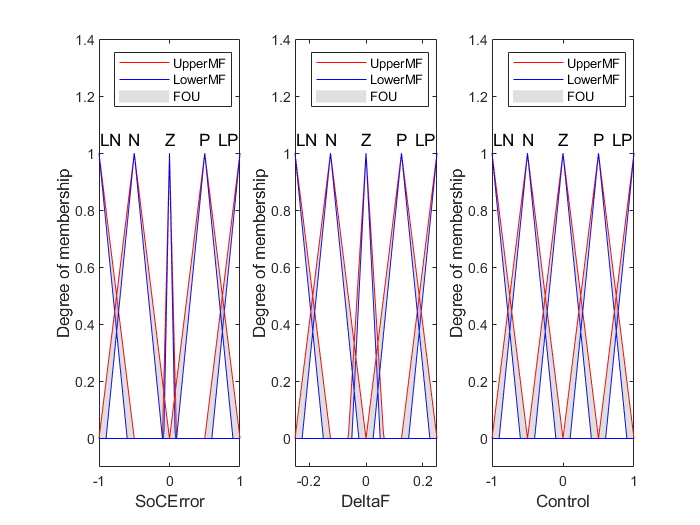

%Creating Type-2 Fuzzy Controller
FLCEFR = readfis('FLCEFR.fis');
FLCEFR_T2 = convertToType2(FLCEFR);
figure
subplot(1,3,1)
plotmf(FLCEFR_T2 ,'input',1)
title('')
subplot(1,3,2)
plotmf(FLCEFR_T2 ,'input',2)
title('')
subplot(1,3,3)
plotmf(FLCEFR_T2 ,'output',1)
title('')

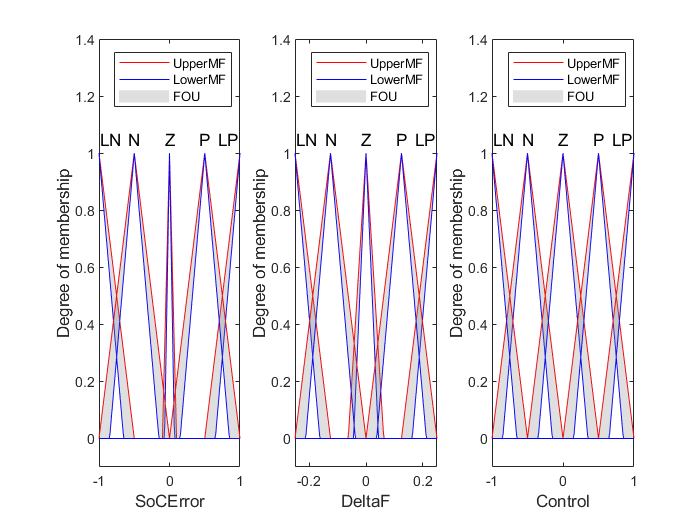

% Modifying FOU for imput MF of controller
for i = 1:length(FLCEFR_T2.Inputs)
    for j = 1:length(FLCEFR_T2.Inputs(i).MembershipFunctions)
        FLCEFR_T2.Inputs(i).MembershipFunctions(j).LowerLag = 0.3;
        FLCEFR_T2.Inputs(i).MembershipFunctions(j).LowerScale = 1;
        end
end
for i = 1:length(FLCEFR_T2.Outputs)
    for j = 1:length(FLCEFR_T2.Outputs(i).MembershipFunctions)
        FLCEFR_T2.Outputs(i).MembershipFunctions(j).LowerLag = 0.3;
        FLCEFR_T2.Outputs(i).MembershipFunctions(j).LowerScale = 1;
        end
end
figure
subplot(1,3,1)
plotmf(FLCEFR_T2 ,'input',1)
title('')
subplot(1,3,2)
plotmf(FLCEFR_T2 ,'input',2)
title('')
subplot(1,3,3)
plotmf(FLCEFR_T2 ,'output',1)
title('')